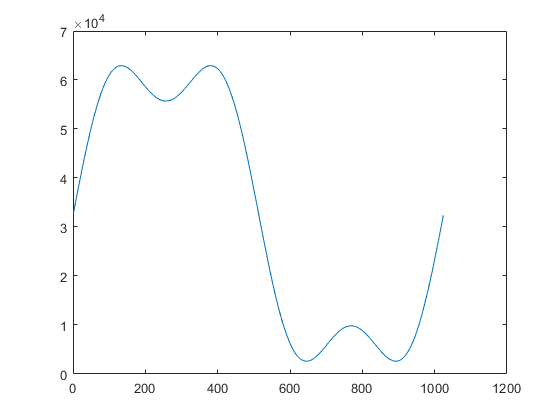

rom_xi = zeros(1,1024);
for xi_i = 0:1023
    rom_xi(xi_i+1) = ceil(32767*(sin(xi_i*2*pi/1024)+0.3*sin(3*xi_i*2*pi/1024))+32767);
end

plot(rom_xi);


float32_xi = dec2hex(rom_xi);
f_xi = fopen ('E:/FPGA_prjs/2CH_X1_MEMORISOR/2ch_x1_memorisor_fpga/2ch_x1_memorisor_fpga.srcs/sources_1/chaotic_dds/DDS/RAM/harm16bit.coe','w');
fprintf(f_xi,'memory_initialization_radix = 16;\n', rom_xi);
fprintf(f_xi,'memory_initialization_vector =\n', rom_xi);
for i1=1:1024
    fprintf(f_xi,'%s\n',float32_xi(i1,:));
end
fclose(f_xi);